# Assignment 2

**Dynamical Systems and Non-Linear Dynamics**

**Giorgia Del Missier – i6292403**

## Stable oscillations in an ecological model

a) Interpret these equations for *N* and *P* biologically: describe the meaning of the parameters and the interactions between *N* and *P* present in the model.

The model is constructed in the form of differential equations with time being the independent variable. 

The growth of the prey population is given by a logistic equation, with r1 being the per capita growth and K the carrying capacity - i.e. the maximum number of prey allowed by some limited resource. The second term in the equation describes the predation rate, with w being its maximum when the predator cannot kill any more preys even when available and d being a constant that determines the speed of functional response at low prey densities.

The predator population also follows a logistic growth function: r2 is again the per capita growth rate while the carrying capacity is given by the number of prey present. The parameter j determines the number of prey that is needed for one predator.

b) Create a phase portrait for parameter values r1=1, r2=0.1, K=7, d=1, j=1 and w=0.3 (nullclines, fixed points, trajectories) and plot the values of *N(t) *and *P(t)* over time to illustrate the behaviour of the system for different initial conditions.

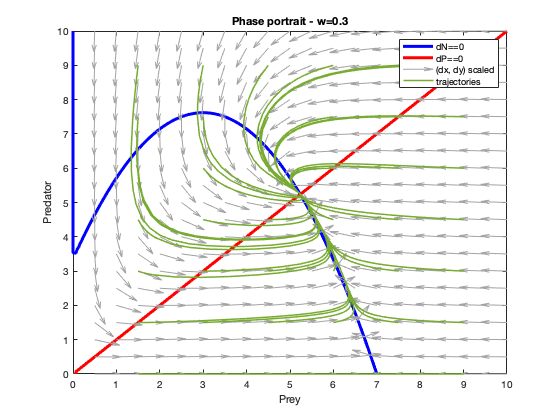

r1 = 1; 
r2 = 0.1; 
K = 7;
d = 1;
j = 1;
w = 0.3;

figure()

% plot the nullclines dN = 0 and dP = 0
interval = [0,10];
fimplicit(@(N, P) r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N), interval, 'b', 'displayname', 'dN == 0', 'lineWidth', 3);
hold on;
fimplicit(@(N, P) r2.*P.*(1-((j.*P)./N)), interval, 'r', 'displayname', 'dP == 0', 'lineWidth', 3);
legend;

% compute the values of dN and dP in the grid
[N, P] = meshgrid(0:.5:10, 0:.5:10);
dN = r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N);
dP = r2.*P.*(1-((j.*P)./N));
scaling = sqrt(dN.^2 + dP.^2) / 2;

% visualize the direction field
quiver(N, P, dN./scaling, dP./scaling, 'Color', '#A4A4A4', 'displayname', '(dx, dy) scaled', 'lineWidth', 1);
hold on;

% define x and y as a vector x = (x,y)
functionHandle = @(t,x) ([r1.*x(1).*(1 - (x(1)./K))-(w.*x(1).*x(2))./(d+x(1)); r2.*x(2).*(1-((j.*x(2)./x(1))))]);

% simulate and plot a trajectory, starting at different values of [N0, P0]
for N0 = 0:1.5:10
    for P0 = 0:1.5:10
        [t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
        plot(trajectory(:, 1), trajectory(:, 2), 'lineWidth', 1.5, 'displayname', 'trajectory', 'Color','#77AC30');
        hold on
    end
end
legend('dN==0','dP==0','(dx, dy) scaled','trajectories')
xlim([0 10]);
ylim([0 10]);
xlabel('Prey')
ylabel('Predator')
title('Phase portrait - w=0.3')
hold off

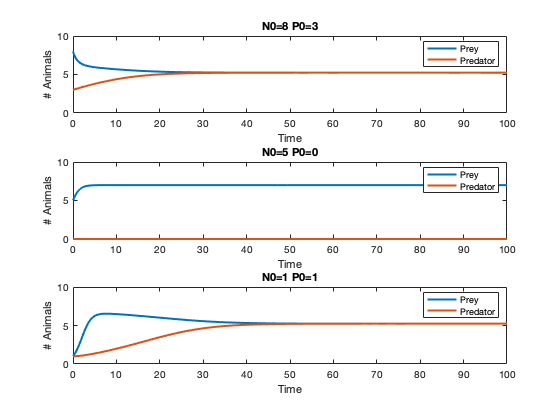

figure()

subplot(3,1,1)
N0 = 8;
P0 = 3;
[t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
plot(t, trajectory(:,1), t, trajectory(:,2),'LineWidth',2)
ylim([0 10]);
legend('Prey', 'Predator')
xlabel('Time')
ylabel('# Animals')
title('N0=8 P0=3')

subplot(3,1,2)
N0 = 5;
P0 = 0;
[t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
plot(t, trajectory(:,1), t, trajectory(:,2),'LineWidth',2)
ylim([0 10]);
legend('Prey', 'Predator')
xlabel('Time')
ylabel('# Animals')
title('N0=5 P0=0')

subplot(3,1,3)
N0 = 1;
P0 = 1;
[t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
plot(t, trajectory(:,1), t, trajectory(:,2),'LineWidth',2)
ylim([0 10]);
legend('Prey', 'Predator')
xlabel('Time')
ylabel('# Animals')
title('N0=1 P0=1')

c) Determine the fixed points of the system for these parameters values. Classify each fixed point by computing the eigenvalues and eigenvectors of the Jacobian matrix at each of the fixed points.

The fixed points for the parameters set above and w=0.3 exist at (7,0) and (5.23672, 5.23672). Their stability can be classified by using the Jacobian matrix as follows:

% jacobian and eigenvalues
jacobianM = @(w,N,P)([ -(d.*P.*w)./((d+N).^2)-(2.*N.*r1)./K+r1, ...
    -(N.*w)/(d+N); ...
    (j.*P.^2.*r2)/(N.^2), ...
    r2-(2.*j.*P.*r2)./N]);

w = 0.3;
eig(jacobianM(w,7,0))

ans =    -1.0000
    0.1000


In this case, one eigenvalue is positive and one is negative, thus the fixed point is a stable node.

eig(jacobianM(w,5.23672,5.23672))

ans =    -0.4682
   -0.1684


Here, both eigenvalues are negative, thus the fixed point is a saddle node.

d) Set w=1 and observe what happens to the phase portrait. What is this change called (be specific)? Motivate your findings using the Jacobian matrix at the fixed point where the change takes place between w=0.3 and w=1.

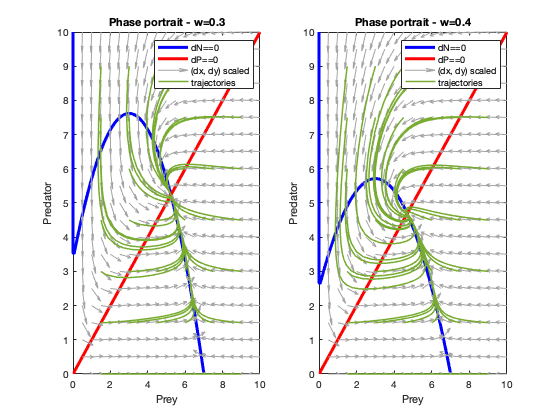

figure()

subplot(1,2,1)
w = 0.3;

% plot the nullclines dN = 0 and dP = 0
interval = [0,10];
fimplicit(@(N, P) r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N), interval, 'b', 'displayname', 'dN == 0', 'lineWidth', 3);
hold on;
fimplicit(@(N, P) r2.*P.*(1-((j.*P)./N)), interval, 'r', 'displayname', 'dP == 0', 'lineWidth', 3);
legend;

% compute the values of dN and dP in the grid
[N, P] = meshgrid(0:.5:10, 0:.5:10);
dN = r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N);
dP = r2.*P.*(1-((j.*P)./N));
scaling = sqrt(dN.^2 + dP.^2) / 2;

% visualize the direction field
quiver(N, P, dN./scaling, dP./scaling, 'Color', '#A4A4A4', 'displayname', '(dx, dy) scaled', 'lineWidth', 1);
hold on;

% define x and y as a vector x = (x,y)
functionHandle = @(t,x) ([r1.*x(1).*(1 - (x(1)./K))-(w.*x(1).*x(2))./(d+x(1)); r2.*x(2).*(1-((j.*x(2)./x(1))))]);

% simulate and plot a trajectory, starting at different values of [N0, P0]
for N0 = 0:1.5:10
    for P0 = 0:1.5:10
        [t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
        plot(trajectory(:, 1), trajectory(:, 2), 'lineWidth', 1.5, 'displayname', 'trajectory', 'Color','#77AC30');
        hold on
    end
end
legend('dN==0','dP==0','(dx, dy) scaled','trajectories')
xlim([0 10]);
ylim([0 10]);
xlabel('Prey')
ylabel('Predator')
title('Phase portrait - w=0.3')
hold off

subplot(1,2,2)
w = 0.4;

% plot the nullclines dN = 0 and dP = 0
interval = [0,10];
fimplicit(@(N, P) r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N), interval, 'b', 'displayname', 'dN == 0', 'lineWidth', 3);
hold on;
fimplicit(@(N, P) r2.*P.*(1-((j.*P)./N)), interval, 'r', 'displayname', 'dP == 0', 'lineWidth', 3);
legend;

% compute the values of dN and dP in the grid
[N, P] = meshgrid(0:.5:10, 0:.5:10);
dN = r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N);
dP = r2.*P.*(1-((j.*P)./N));
scaling = sqrt(dN.^2 + dP.^2) / 2;

% visualize the direction field
quiver(N, P, dN./scaling, dP./scaling, 'Color', '#A4A4A4', 'displayname', '(dx, dy) scaled', 'lineWidth', 1);
hold on;

% define x and y as a vector x = (x,y)
functionHandle = @(t,x) ([r1.*x(1).*(1 - (x(1)./K))-(w.*x(1).*x(2))./(d+x(1)); r2.*x(2).*(1-((j.*x(2)./x(1))))]);

% simulate and plot a trajectory, starting at different values of [N0, P0]
for N0 = 0:1.5:10
    for P0 = 0:1.5:10
        [t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
        plot(trajectory(:, 1), trajectory(:, 2), 'lineWidth', 1.5, 'displayname', 'trajectory', 'Color','#77AC30');
        hold on
    end
end
legend('dN==0','dP==0','(dx, dy) scaled','trajectories')
xlim([0 10]);
ylim([0 10]);
xlabel('Prey')
ylabel('Predator')
title('Phase portrait - w=0.4')
hold off

eig(jacobianM(w,4.69192,4.69192))

ans =   -0.2492 + 0.1034i
  -0.2492 - 0.1034i


A first change in the phase portrait happens between w=0.36 and w=0.37: after this value, in fact, the eigenvalues at the fixed point start having a complex part, thus indicating that the stable node has turned into a spiral. Since the eigenvalues' real part is negative, the fixed point is a stable spiral.

figure()

subplot(1,2,1)
w = 0.8;

% plot the nullclines dN = 0 and dP = 0
interval = [0,10];
fimplicit(@(N, P) r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N), interval, 'b', 'displayname', 'dN == 0', 'lineWidth', 3);
hold on;
fimplicit(@(N, P) r2.*P.*(1-((j.*P)./N)), interval, 'r', 'displayname', 'dP == 0', 'lineWidth', 3);
legend;

% compute the values of dN and dP in the grid
[N, P] = meshgrid(0:.5:10, 0:.5:10);
dN = r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N);
dP = r2.*P.*(1-((j.*P)./N));
scaling = sqrt(dN.^2 + dP.^2) / 2;

% visualize the direction field
quiver(N, P, dN./scaling, dP./scaling, 'Color', '#A4A4A4', 'displayname', '(dx, dy) scaled', 'lineWidth', 1);
hold on;

% define x and y as a vector x = (x,y)
functionHandle = @(t,x) ([r1.*x(1).*(1 - (x(1)./K))-(w.*x(1).*x(2))./(d+x(1)); r2.*x(2).*(1-((j.*x(2)./x(1))))]);

% simulate and plot a trajectory, starting at different values of [N0, P0]
for N0 = 0:1.5:10
    for P0 = 0:1.5:10
        [t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
        plot(trajectory(:, 1), trajectory(:, 2), 'lineWidth', 1.5, 'displayname', 'trajectory', 'Color','#77AC30');
        hold on
    end
end
legend('dN==0','dP==0','(dx, dy) scaled','trajectories')
xlim([0 10]);
ylim([0 10]);
xlabel('Prey')
ylabel('Predator')
title('Phase portrait - w=0.8')
hold off

eig(jacobianM(w,2.8533,2.8533))

ans =   -0.0345 + 0.2344i
  -0.0345 - 0.2344i


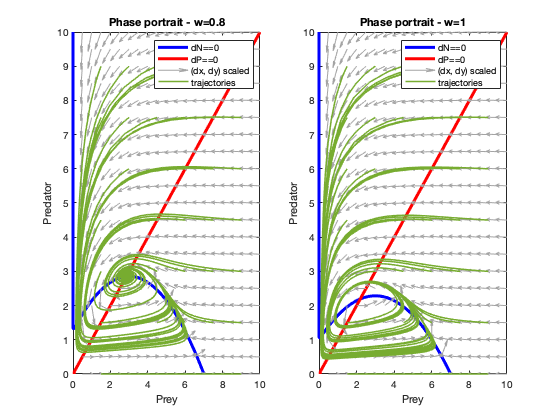

subplot(1,2,2)
w = 1;

% plot the nullclines dN = 0 and dP = 0
interval = [0,10];
fimplicit(@(N, P) r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N), interval, 'b', 'displayname', 'dN == 0', 'lineWidth', 3);
hold on;
fimplicit(@(N, P) r2.*P.*(1-((j.*P)./N)), interval, 'r', 'displayname', 'dP == 0', 'lineWidth', 3);
legend;

% compute the values of dN and dP in the grid
[N, P] = meshgrid(0:.5:10, 0:.5:10);
dN = r1.*N.*(1 - (N./K))-(w.*N.*P)./(d+N);
dP = r2.*P.*(1-((j.*P)./N));
scaling = sqrt(dN.^2 + dP.^2) / 2;

% visualize the direction field
quiver(N, P, dN./scaling, dP./scaling, 'Color', '#A4A4A4', 'displayname', '(dx, dy) scaled', 'lineWidth', 1);
hold on;

% define x and y as a vector x = (x,y)
functionHandle = @(t,x) ([r1.*x(1).*(1 - (x(1)./K))-(w.*x(1).*x(2))./(d+x(1)); r2.*x(2).*(1-((j.*x(2)./x(1))))]);

% simulate and plot a trajectory, starting at different values of [N0, P0]
for N0 = 0:1.5:10
    for P0 = 0:1.5:10
        [t, trajectory] = ode45(functionHandle, [0,100], [N0;P0]);
        plot(trajectory(:, 1), trajectory(:, 2), 'lineWidth', 1.5, 'displayname', 'trajectory', 'Color','#77AC30');
        hold on
    end
end
legend('dN==0','dP==0','(dx, dy) scaled','trajectories')
xlim([0 10]);
ylim([0 10]);
xlabel('Prey')
ylabel('Predator')
title('Phase portrait - w=1')
hold off

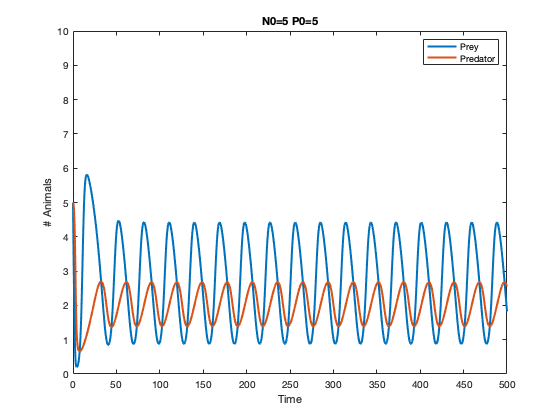

figure()

N0 = 5;
P0 = 5;
[t, trajectory] = ode45(functionHandle, [0,500], [N0;P0]);
plot(t, trajectory(:,1), t, trajectory(:,2),'LineWidth',2)
ylim([0 10]);
legend('Prey', 'Predator')
xlabel('Time')
ylabel('# Animals')
title('N0=5 P0=5')

eig(jacobianM(w,2.19258,2.19258))

ans =    0.0292 + 0.2280i
   0.0292 - 0.2280i


A second change in the phase portrait occurs between w=0.89 and w=0.9, where a supercritical Hopf bifurcation occurs: the stable spiral loses its stability and a stable limit cycle is created, as shown in the phase portrait figure. This change can also be observed when computing the eigenvalues: when the Hopf bifurcation occurs, the eigenvalues will only have a imaginary part. After the bifurcation has occurred, the eigenvalues' real part becomes positive, as shown above.